# **Effective Solar House Design**

*Authors: *Drew Pang and Kelly Stellmacher

Traditional houses attempt to separate the temperature-controlled air from the outside air but add windows to let natural light. While these homes have gotten more energy efficient due to advances in insulation, solar houses can be more energy efficient. By contrast, solar homes attempt to heat themselves through large windows facing south. During Winter, the sun shines into the house and radiates heat energy off of the floor. However, during the Summer when the sun is higher, the soffit blocks the sun from entering the already warm house. 

 We can use thermodynamics to model a solar house to estimate the effects of parameters. Let's take a look at the specific solar house we are modeling:

**Question**: What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?

Why is this interesting? We are asking a design question, and through our model, we will be able to determine the effects of the thickness of our walls. This may help architects and homeowners looking to design and build solar houses.

**Method/model:**

- How are you going to answer your question? 

- What assumptions are you making? Are these good or bad assumptions?

- How did you develop and refine your model?

- What additional representations of your model help to communicate it to your reader (e.g., equations, stock and flow diagrams)? 

- How did you set the parameters of your model?

- How did you verify your model?

- Optional: If you had more time, what plan would you use to validate your model?

We are going to answer our question by tracking the flow of energy from the sun into the floor, then into the room and out the walls. We decided that the floor was the simplest stock in which we can store energy, so the floor will conduct the energy into the room. 

We developed the following scematic diagram:

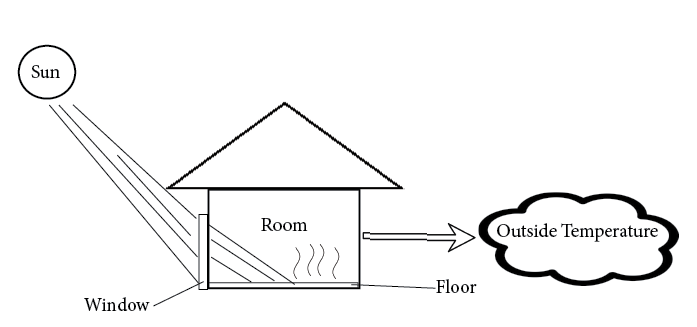

Where energy radiates from the sun, through the window of the house, into the floor, and then conducts from the floor into the air contained in the house. The energy then leaves the house via convecting through the walls. 

Using the scematic, we developed the following stock and flow diagram:

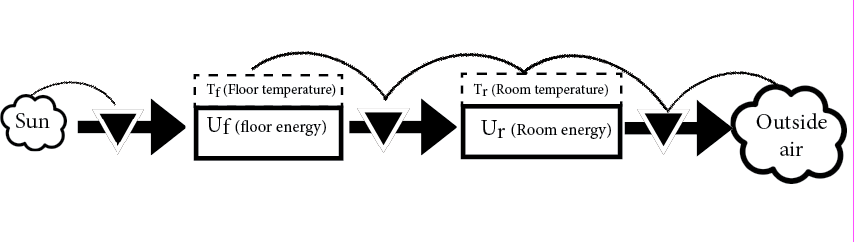

Where the flow from the sun to the floor is radiation, the flow from the floor to the room is convection, and the flow from the room to the outside air is conduction. 

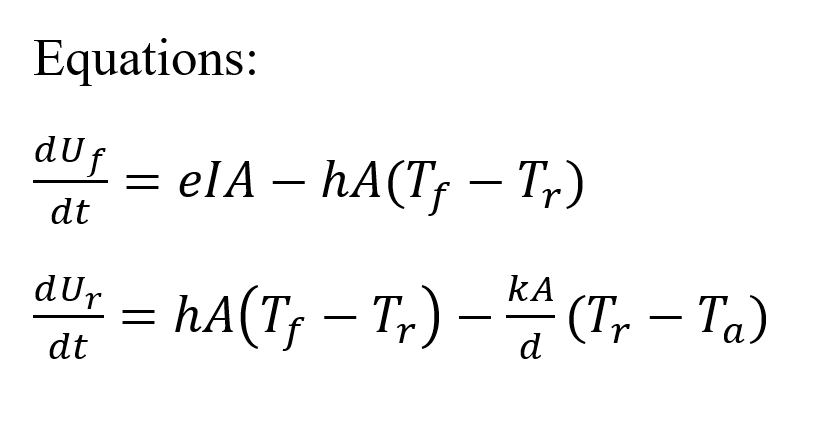

Through research into the different parameters of the system, we managed to gain reliable approximations for all of the factors contributing to our model. The parameter settings needed to be revised multiple times for the final values to be settled on.  

Parameters: 

- Tf(1) = 293; floor starting temperature (K)

- Tr(1) = 293; house int starting temperature (K)

- Ta = 263.56; external temperature (K)

- w = 10; sidelength of house (m)

- wt = .30; thickness of walls (m)

- wf = .05715; thickness of floor (m)

- I = 170.14; incident solar radiation (w/m^2)

- e = 0.885; emmisivity of floor (oak) (j/m^2)

- h_a = 0.026; thermal conductivity of air (w/m)

- h_w = 0.05; thermal conductivity of walls (insulation) (w/m)

- h_f = 0.170; thermal conductivity of floor (wood) (w/m)

- s_f = 1850; specific heat of floor(j/kg C)

- s_a = 1005; specific heat of air (j/kg C)

- d = 1.293; density of air (kg/m^3)

- d_f = 745; density of floor (kg/m^3)

Assumptions for our model inlcude:

- The structural integrity of the house will not be jepordized based on the material the walls are composed of. 

- The roof is made of the same material as the walls. 

- The aperture of the window will remain constant.

- The Sun zenith angle remains the same.

- The house is empty: no people or furniture is present to alter energy content of the room

- There is nothing obstructing the sunlight from reaching the house. 

[Tt,Dt] = solar_house_day_night();

Ds = 1

Tf_0 = 293

Tr_0 = 293

Ds = 69

Tf_0 = 314.8859

Tr_0 = 311.8296

Ds = 89

Tf_0 = 296.5772

Tr_0 = 294.9899

Ds = 65

Tf_0 = 317.3614

Tr_0 = 314.1581

Ds = 89

Tf_0 = 298.1686

Tr_0 = 296.5127

Ds = 65

Tf_0 = 318.5244

Tr_0 = 315.2678

Ds = 89

Tf_0 = 298.9180

Tr_0 = 297.2272

Ds = 65

Tf_0 = 319.0718

Tr_0 = 315.7902

Ds = 89

Tf_0 = 299.2707

Tr_0 = 297.5635

Ds = 65

Tf_0 = 319.3294

Tr_0 = 316.0360

Ds = 89

Tf_0 = 299.4367

Tr_0 = 297.7218

Ds = 65

Tf_0 = 319.4507

Tr_0 = 316.1517

Ds = 89

Tf_0 = 299.5148

Tr_0 = 297.7963

Ds = 65

Tf_0 = 319.5077

Tr_0 = 316.2062

Ds = 89

Tf_0 = 299.5516

Tr_0 = 297.8314

Ds = 65

Tf_0 = 319.5346

Tr_0 = 316.2318

Ds = 89

Tf_0 = 299.5689

Tr_0 = 297.8479

Ds = 65

Tf_0 = 319.5473

Tr_0 = 316.2439

Ds = 89

Tf_0 = 299.5771

Tr_0 = 297.8556

Ds = 65

Tf_0 = 319.5532

Tr_0 = 316.2495

Ds = 89

Tf_0 = 299.5809

Tr_0 = 297.8593

Ds = 65

Tf_0 = 319.5560

Tr_0 = 316.2522

Ds = 89

Tf_0 = 299.5827

Tr_0 = 297.8610

Ds = 65

Tf_0 = 319.5573

Tr_0 = 316.2535

Ds = 89

Tf_0 = 299.5836

Tr_0 = 297.8618

Ds = 65

Tf_0 = 319.5579

Tr_0 = 316.2541

Ds = 89

Tf_0 = 299.5840

Tr_0 = 297.8622

Ds = 65

Tf_0 = 319.5582

Tr_0 = 316.2543

Ds = 89

Tf_0 = 299.5842

Tr_0 = 297.8624

Ds = 65

Tf_0 = 319.5584

Tr_0 = 316.2545

Ds = 89

Tf_0 = 299.5842

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5584

Tr_0 = 316.2545

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

Ds = 89

Tf_0 = 299.5843

Tr_0 = 297.8625

Ds = 65

Tf_0 = 319.5585

Tr_0 = 316.2546

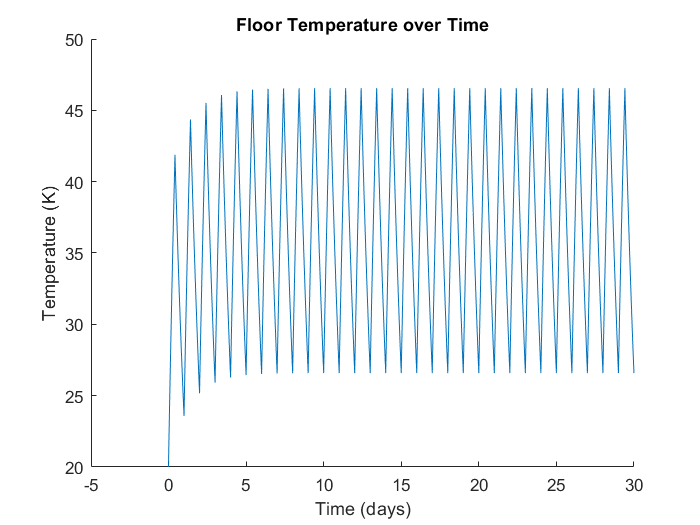

figure(1);
clf; hold on;
title('Floor Temperature over Time');
plot(Tt/(24*3600),Dt(:,1));
xlabel('Time (days)')
ylabel('Temperature (C)')

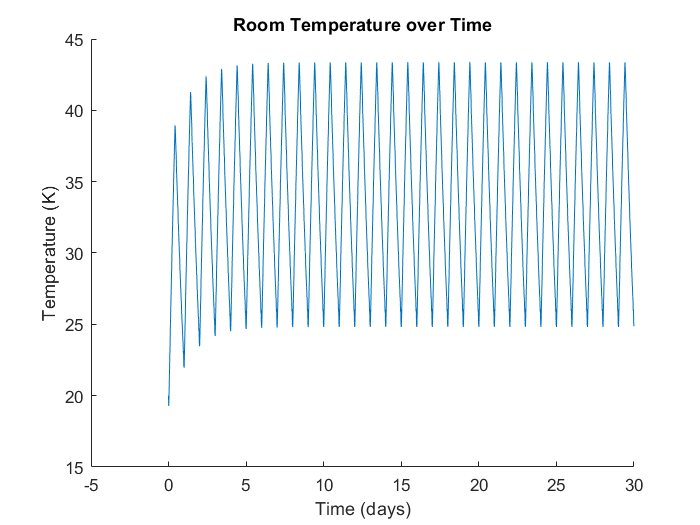


figure(2)
clf; hold on;
title('Room Temperature over Time');
plot(Tt/(24*3600),Dt(:,2));
xlabel('Time (days)')
ylabel('Temperature (C)')

Verifying this model is difficult because the total energy is not able to be tracked, as it is contained in stocks that are not monitored. 

If we had more time and resources for this project, we could verify the results by constructing a miniature model house with the materials we specified, setting up a controllable heat source, then monitor the change in temperature over time.  

**Results:**

Our model indicates that the temperature of the room rises and falls every day and night, with overall high temperatures of about 42.5 degrees Celcius and lows of about 26 degrees Celcius. 

**Interpretation:**

- How do the results answer the question?

- Do you think the answer is a good one? 

- What are the limitations of your model? 

- If you were going to continue developing your model, what next steps might you take? 

Our model is limited in that it only accounts for conduction through the walls, but fails to account for whether there are any doors or open windows where energy could convect directly out of the house. It is also limited to a very specific location with a specific amount of solar radiation acting on it. 

If we were to continue iterating on our model, we could lengthen the timeframe to a year and examine the impact of changing seasons. We could also add a flow from the floor into the ground to more accurately simlate the change in energy in the house. 